# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.3 Stripmap Point Spread Function

## Calculate the spectral support (m)

% Clear the workspace
clear

% Speed of light (m/s)
c = 299792458;

% Waveform bandwidth (Hz)
waveform_bandwidth = 20e6;

% Operating frequency (Hz)
operating_frequency = 1e9;

% Cross-range resolution (m)
cross_range_resolution = 4;

% Calculate the antenna width (m)
antenna_width = 2 * cross_range_resolution;

% Calculate the min and max wavelengths
wavelength_min = c / (operating_frequency + 0.5 * waveform_bandwidth);
wavelength_max = c / (operating_frequency - 0.5 * waveform_bandwidth);

% Calculate the min and max wavenumber
kmin = 2 * pi / wavelength_max;
kmax = 2 * pi / wavelength_min;

% Calculate the spectral support (rad/m) Equations (2.8) and (2.9)
dkx = 2 * (kmax - kmin);
dky = 4 * pi / antenna_width;

## Set the target location

x_target = 5;
y_target = 2;

## Calculate the point spread function

$\textrm{psf}=\textrm{sinc}\left(\frac{\Delta \;k_x x\;}{2\;\pi \;}\right)\textrm{sinc}\left(\frac{\Delta \;k_y y\;}{2\pi \;}\right)$   Equation (2.10)

% Set up the x and y grid
x = linspace(-15, 15, 1e3);

y = linspace(-15, 15, 1e3);

[xs, ys] = meshgrid(x, y);

% Calculate the PSF
psf = sinc(dkx * (xs - x_target) / (2 * pi)) .* sinc(dky * (ys - y_target) / (2 * pi));

### Plot the results

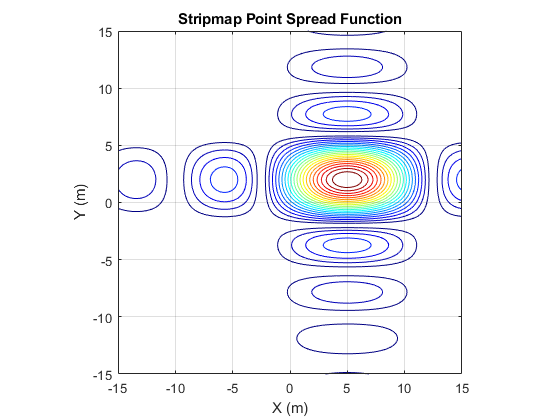

figure;
contour(xs, ys, abs(psf), 20);
colormap jet;
xlabel('X (m)')
ylabel('Y (m)')
title('Stripmap Point Spread Function')
axis square
grid on;